# Recycling Analysis Demo

Use WasteAnalysis function to obtain the potencial saving cost of waste recycling

#### Read the Data Model

file="C:\Users\ctorr\Documents\Proyectos\TaesLab\Examples\cgam\cgam_model.json";
data=ReadDataModel(file);

#### Set the parameters

if ~data.isWaste
    disp('The model has NOT waste');
    return
end
WasteFlows=convertCharsToStrings(data.WasteFlows);
ActiveWaste=convertStringsToChars(WasteFlows(1));
States=convertCharsToStrings(data.StateNames);
State=convertStringsToChars(States(1));
CostTables='DIRECT';
if data.isResourceCost
    CostTables='ALL';
    Samples=convertCharsToStrings(data.SampleNames);
    ResourceSample=convertStringsToChars(Samples(1));
end

#### Get Waste Analysis Results

res=WasteAnalysis(data,'ActiveWaste',ActiveWaste,'State',State,...
    'CostTables',CostTables,'ResourceSample',ResourceSample);

#### Show the Results

Show the waste allocation table and display de waste recycling graphs for direct and generalizad costs

ShowResults(res,'Table','wa');


Waste Allocation Table  (%) - REF

 Key            QG
———————————————————
 COMB        76.80
 CMP          9.30
 TRB          5.00
 APH          8.90



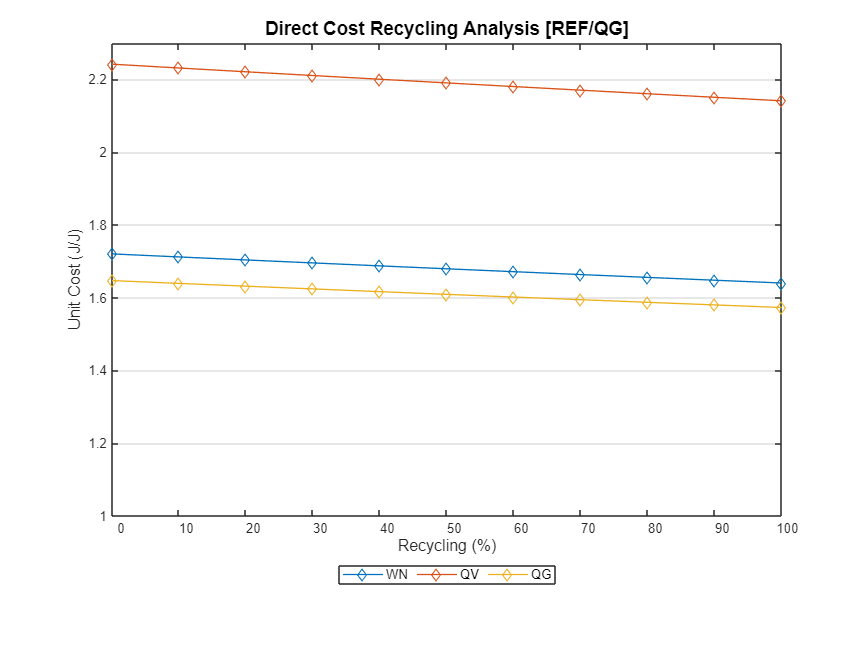

ShowGraph(res,'Graph',cType.Tables.WASTE_RECYCLING_DIRECT);

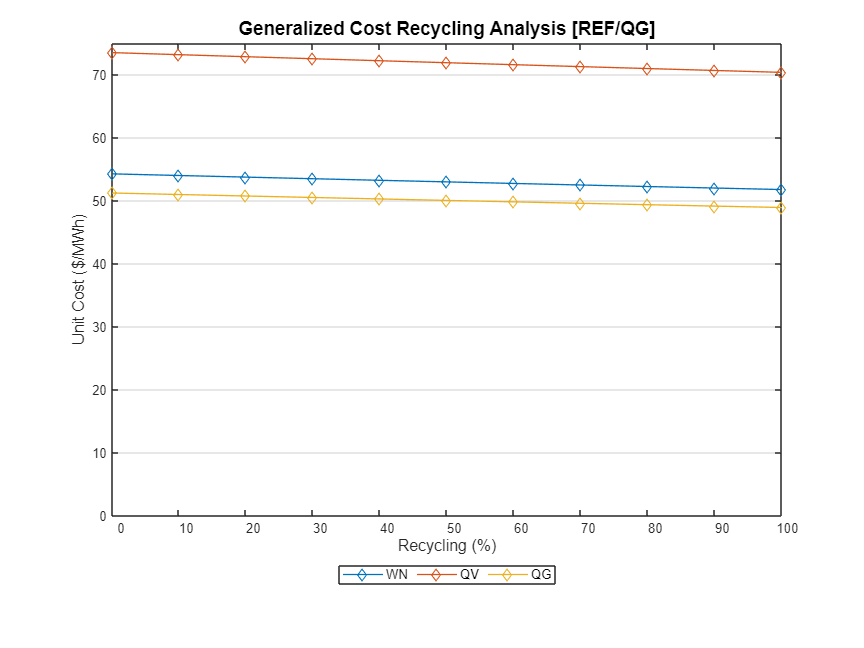

ShowGraph(res,'Graph',cType.Tables.WASTE_RECYCLING_GENERAL);

#### Additional Help

help WasteAnalysis 

 WasteAnalysis - Perform a waste analysis of a plant state.
    It calculates the waste allocation for the criteria defined in the data model.
    If the option 'Recycling' is active, it calculates the tables with the direct
    and/or generalized costs as a function of the recycling of waste from 0 to 100 percent 
 
    Syntax
      res=WasteAnalysis(data,Name,Value)
 
    Input Arguments
  	  data - cDataModel object whose contains the thermoeconomic data model
 
    Name-Value Arguments
      State - Thermoeconomic state. If missing first sample is taken
        array char | string
      Recycling: Waste Recycling analysis 
        false | true (default)
      ActiveWaste: Waste Flow key to analyze. If missing first sample is taken
        array char | string
      CostTables - Indicate which cost tables are calculated
        'DIRECT' calculates direct exergy cost tables
        'GENERALIZED' calculates generalized exergy cost tables
        'ALL' 